# Sample 12-1

## 画像復元

ウィーナーフィルタ

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image restoration

Wiener filter

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

sgmuint8 = 10; 
sgmw = sgmuint8/255;

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/kodim23.png')));
sgmu = std(u(:));
meanu = mean(u(:));

## 観測画像

(Observation image)

カメラの動きによって生じるボケ画像を生成．(Generate a blurred image that might result from camera motion. )

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


% Definition of measurment process
psf = fspecial('motion',31,21);
measureproc = @(x) imfilter(x,psf,'conv','circular');
% Simulation of AWGN
v = imnoise(measureproc(u),'gaussian',0,sgmw^2);

### ウィーナーフィルタ

(Wiener filter)

画像 $\mathbf{u}$に対する仮定 (Assumptions on the original image $\mathbf{u}$)

- 
$$\mathbf{u}\sim\mathrm{Norm}\left(\mathbf{u}|\mathbf{\mu}_u=\mathbf{0},\sigma_u^2\mathbf{I}\right)$$


#### 問題設定 (Problem settings):

        
$$\widehat{\mathbf{u}}=\arg \min _{\mathbf{u}} \frac{1}{2\sigma_{w}^{2}}\|\mathbf{v}-\mathbf{P} \mathbf{u}\|_{2}^{2}+\frac{1}{2\sigma_{u}^{2}}\left\| \mathbf{u}\right\|_{2}^{2}$$


#### 解 (Solution):

        
$$\widehat{\mathbf{u}}=\left(\mathbf{P}^{T} \mathbf{P}+  \frac{\sigma_{w}^{2}}{ \sigma_{u}^{2}}\mathbf{I}\right)^{-1} \mathbf{P}^{T} \mathbf{v}\stackrel{\mathrm{DFT}}{\longleftrightarrow} \widehat{\mathrm{U}}[\mathbf{k}]=\frac{\overline{P[\mathbf{k}]}}{|P[\mathbf{k}]|^{2}+\sigma_{w}^{2}/\sigma_{u}^{2}} \mathrm{V}[\mathbf{k}]$$


ただし，循環畳み込み行列 $\mathbf{P}$ に対して，(where, for the circular convolution matrix $\mathbf{P}$,)

        
$$\mathbf{P}^{T} \stackrel{\mathrm{DFT}}{\longleftrightarrow}\overline{P[\mathbf{k}]}$$


        
$$\mathbf{P}^{T} \mathbf{P}\stackrel{\mathrm{DFT}}{\longleftrightarrow} \overline{P[\mathbf{k}]}P[\mathbf{k}]=|P[\mathbf{k}]|^{2}$$


% Determine the DFT points
nPoints = size(u); % 2.^nextpow2(size(u))
% Ratio of variances between noise w and signal u (ideal estimation)
nsr = sgmw^2/sgmu^2;
% DFT(OTF) of PSF, where the phase response is adjusted to zero  
P = psf2otf(psf,nPoints);
% DFT of observation v
V = fftn(v,nPoints);
% DFT of Wiener filter r
R = conj(P)./(abs(P).^2+nsr); 
% IDFT of filtered spectrum
y0 = ifftn(R.*V);
y0 = y0(1:size(u,1),1:size(u,2));

### 逆フィルタ

(Inverse filter)

        
$$\check{\mathbf{u}}=\left(\mathbf{P}^{T} \mathbf{P}\right)^{-1} \mathbf{P}^{T} \mathbf{v}
= \mathbf{P}^{-1} \mathbf{v}\stackrel{\mathrm{DFT}}{\longleftrightarrow} \check{\mathrm{U}}[\mathbf{k}]=\frac{\overline{P[\mathbf{k}]}}{|P[\mathbf{k}]|^{2}} \mathrm{V}[\mathbf{k}]=\frac{1}{P[\mathbf{k}]} \mathrm{V}[\mathbf{k}]$$


% IDFT of filtered spectrum
y1 = ifftn(V./P);
y1 = y1(1:size(u,1),1:size(u,2));

### 画像表示

(Image show)

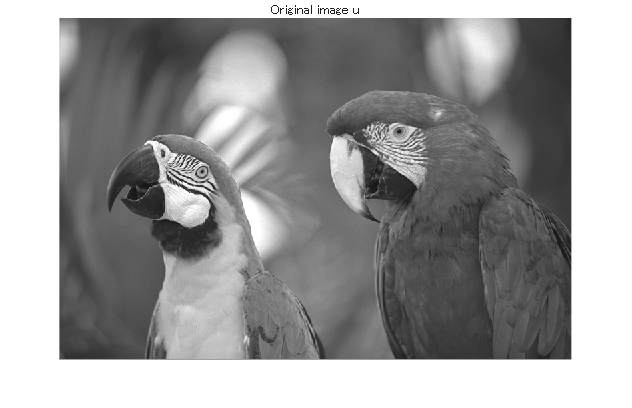

figure(1)
imshow(u);
title('Original image u')

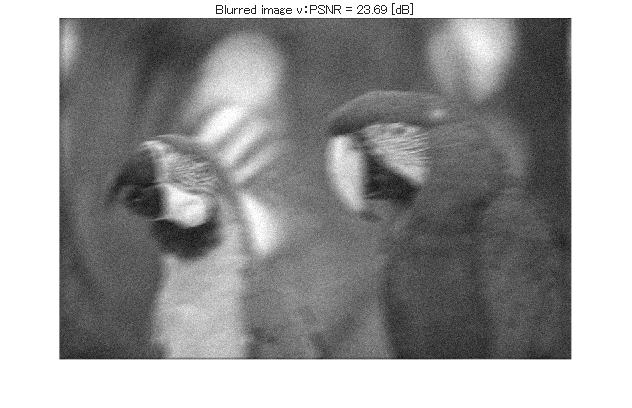

figure(2)
imshow(v)
title(sprintf('Blurred image v：PSNR = %5.2f [dB]',psnr(u,v)))

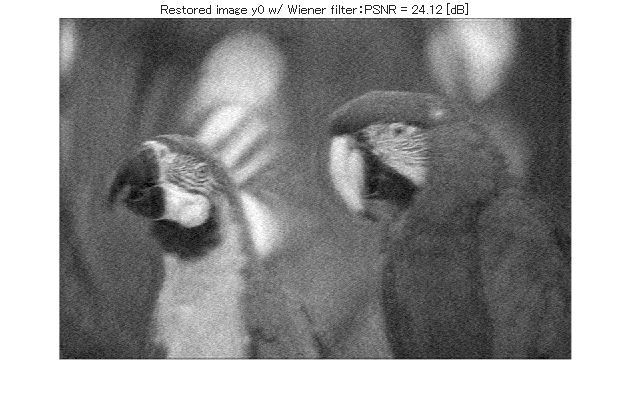

figure(3)
imshow(y0)
title(sprintf('Restored image y0 w/ Wiener filter：PSNR = %5.2f [dB]',psnr(u,y0)))

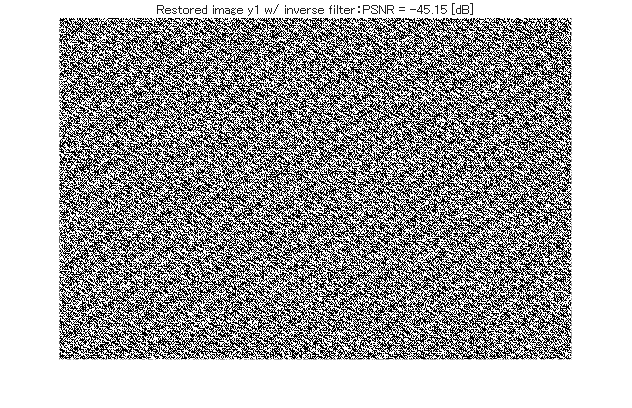

figure(4)
imshow(y1)
title(sprintf('Restored image y1 w/ inverse filter：PSNR = %5.2f [dB]',psnr(u,y1)))

### ウィーナーフィルタ関数

(Wiener filter function)

- DECONVWNR

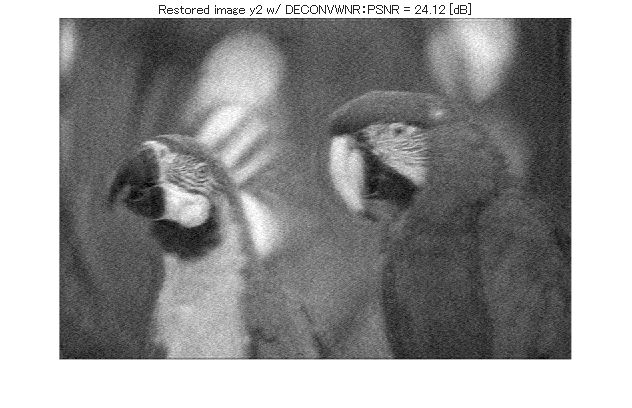

y2 = deconvwnr(v,psf,nsr);
figure(5)
imshow(y2)
title(sprintf('Restored image y2 w/ DECONVWNR：PSNR = %5.2f [dB]',psnr(u,y2)))

© Copyright, Shogo MURAMATSU, All rights reserved.